clc;clear all;close all;
%syms x1 x2 u
%x=[x1;x2];
syms t
syms x [2 1]
syms u
f=sys(t,x,u);
xeq=[0;0];%Punto de equilibrio
ueq=0;%Entrada que sostiene equilibrio
%Ajac=[diff(f,x1) diff(f,x2)]
Ajac=jacobian(f,x);
A=double(subs(Ajac,[x;u],[xeq;ueq]))

A =          0    1.0000
  -21.8000   -3.7037


eig(A)

ans =   -1.8519 + 4.2861i
  -1.8519 - 4.2861i


Bjac=jacobian(f,u)

$$Bjac = \left(\begin{array}{c} 0\\ \frac{2000}{81} \end{array}\right)$$

B=double(subs(Bjac,[x;u],[xeq;ueq]))

B =          0
   24.6914



%Otro P.E. x0=[pi;0], u0=0
xeq=[pi;0];%Punto de equilibrio
ueq=0;%Entrada que sostiene equilibrio

Ajac=jacobian(f,x);
A=double(subs(Ajac,[x;u],[xeq;ueq]))

A =          0    1.0000
   21.8000   -3.7037


eig(A)

ans =     3.1710
   -6.8747



Bjac=jacobian(f,u)

$$Bjac = \left(\begin{array}{c} 0\\ \frac{2000}{81} \end{array}\right)$$

B=double(subs(Bjac,[x;u],[xeq;ueq]))

B =          0
   24.6914



x0=[pi+0.5;0]%condicion inicial

x0 =     3.6416
         0


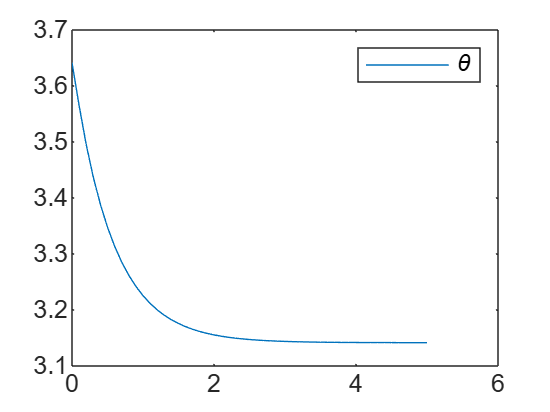

[T,X]=ode45(@(t,x)sys(t,x,controlPD(x)),[0:0.1:5],x0);
figure;
plot(T,X(:,1))
legend('\theta')

U=[]


U =

     []



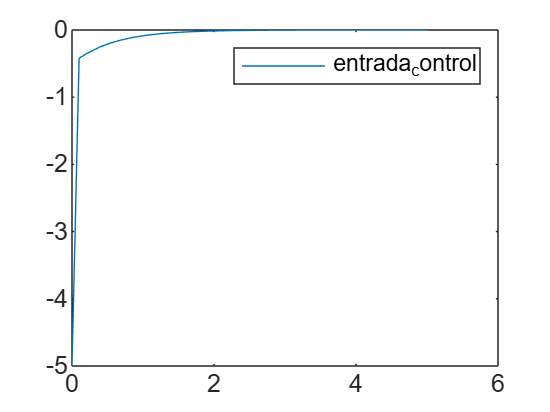

for i=1:length(T)
    U(i,1)=controlPD(X(i,:));
end
plot(T,U);
legend('u')

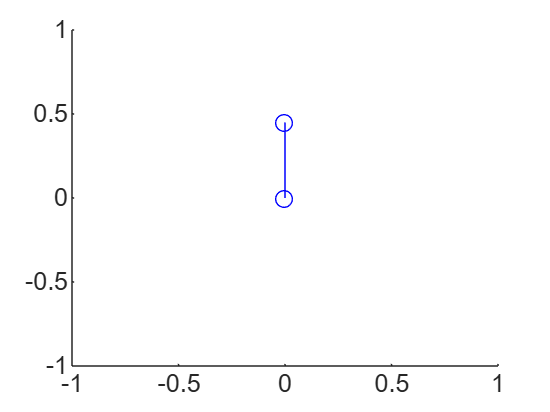

%Animacion
figure
h1=line;hold on;
l=0.45;
pause(2)
for i=1:length(T)
    th_i=X(i,1);
    delete(h1);
    h1=plot([0 l*sin(th_i)],[0 -l*cos(th_i)],'bo-');
    axis([-1 1 -1 1])
    drawnow
    pause(0.05);
end

function u=controlPD(x)
    %x1 posicion, x2 velocidad kp,kd
    x1d=pi;x2d=0;
    kp=10;
    kd=5;
    u=kp*(x1d-x(1))+kd*(x2d-x(2));
end
function dx=sys(t,x,u)
    g=9.81;
    l=0.45;
    B=0.15;
    m=0.2;
    x1=x(1);x2=x(2);
    dx=[x2;-g/l*sin(x1)-B/(m*l^2)*x2+u/(m*l^2)];
end

